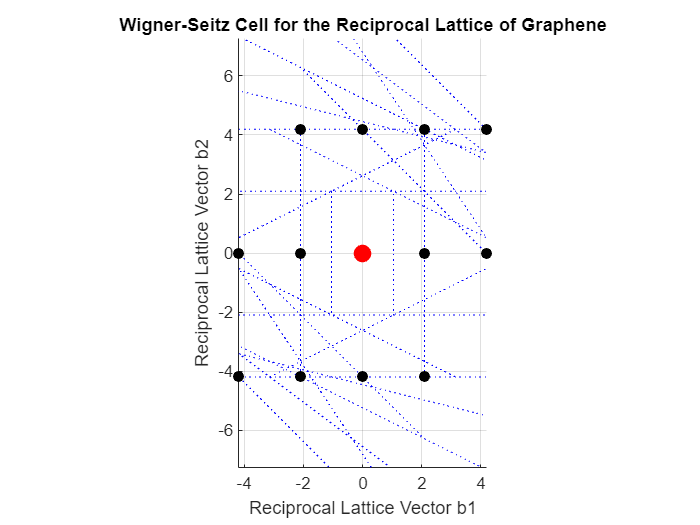

% Define the reciprocal lattice vectors
L = 1; % Lattice constant, set to 1 for simplicity (we can change to modify the limits)
b1 = (4 * pi / (3 * L * sqrt(3))) * [sqrt(3)/2, -3/2];
b2 = (4 * pi / (3 * L * sqrt(3))) * [sqrt(3)/2, 3/2];

% Generate a grid of reciprocal lattice points around the origin
[X, Y] = meshgrid(linspace(-2*b1(1), 2*b1(1), 5), linspace(-2*b2(2), 2*b2(2), 5));

% Calculate the positions of the lattice points
lattice_points = [X(:) + Y(:)/sqrt(3), Y(:) * 2/sqrt(3)];

% Define a function to find the midpoint and perpendicular bisector of two points
find_bisector = @(p1, p2) deal((p1 + p2)/2, [-p2(2) + p1(2), p2(1) - p1(1)]);

% Find the midpoint and normal vector to the line connecting the origin to each lattice point
midpoints = [];
normals = [];
for i = 1:length(lattice_points)
    [mid, norm] = find_bisector([0, 0], lattice_points(i, :));
    midpoints = [midpoints; mid];
    normals = [normals; norm];
end

% Plot the bisectors to find the Brillouin zone boundaries
figure;
hold on;
for i = 1:length(normals)
    % Define a line for each bisector
    t = linspace(-1, 1, 100)'; % Parameter for the line
    bisector_line = [midpoints(i, 1) + t*normals(i, 1), midpoints(i, 2) + t*normals(i, 2)];
    % Plot each line
    plot(bisector_line(:, 1), bisector_line(:, 2), 'b:');
end

% Highlight the lattice points
plot(lattice_points(:, 1), lattice_points(:, 2), 'ko', 'MarkerFaceColor', 'k');

% Highlight the Gamma point
plot(0, 0, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Set axis limits
axis equal;
xlim([-2*b1(1), 2*b1(1)]);
ylim([-2*b2(2), 2*b2(2)]);

% Add a grid, labels, and a title
grid on;
xlabel('Reciprocal Lattice Vector b1');
ylabel('Reciprocal Lattice Vector b2');
title('Wigner-Seitz Cell for the Reciprocal Lattice of Graphene');

hold off;